# Equivalent State-Space Representations for LTI Systems

## Introduction

Consider the discrete-time linear time-invariant (LTI) dynamic system state-space representation of order $n$:


$$\left \{
\begin{array}{l}
x(k+1) = A x(k) + B u(k) \\
y(k) = C x(k) + D u(k)
\end{array}
\right .$$


Let


$$\hat x := T^{-1} x $$


where $$\, T \in {\mathbb R}^{n \times n} \,$ $is a generic non-singular $$n \times n$$ matrix ($$\, {\rm det} (T) \not= 0 \,$$). Then, the equivalent state-space description is given by: 


$$\left \{
\begin{array}{l}
\hat x(k+1) = T^{-1} x(k+1) = T^{-1} A T \hat x(k) + T^{-1} B u(k) = 
\hat A \hat x(k) + \hat B u(k) \\
y(k) = C T \hat x(k) + D u(k) = \hat C \hat x(k) + D u(k)
\end{array}
\right .$$


Hence the two **state space representations** of the considered LTI system are **equivalent**


$$\left \{
\begin{array}{l}
x(k+1) = A x(k) + B u(k) \\
y(k) = C x(k) + D u(k)
\end{array}
\right . \quad \Longleftrightarrow \quad
\left \{
\begin{array}{l}
\hat x(k+1) = \hat A \hat x(k) + \hat B u(k) \\
y(k) = \hat C \hat x(k) + D u(k)
\end{array}
\right . $$


What does it mean those representations are equivalent? Which features are preserved, even though the state variables change?

What you will learn: 

- How to define and apply a state variables linear transformation using Matlab.

- Which features remain unchanged from the previous state-space description to the new one and which features change when passing from one description to another.

## Equivalent State-Space Representations of LTI Systems in MATLAB: a First Example

Given the discrete-time LTI system


$$\left \{
\begin{array}{l}
\left[ \begin{array}{c}
 x_1(k+1)\\
x_2(k+1) \\
x_3(k+1)
\end{array} \right] = \left[ \begin{array}{ccc}
 0 & -1 & 1\\
1 & -2 & 1\\
0 & 1 & -1
\end{array} \right] \,\left[ \begin{array}{c}
 x_1(k)\\
x_2(k) \\
x_3(k)
\end{array} \right]  + \left[ \begin{array}{cc}
1 & 0 \\
1 & 1 \\
1 & 2
\end{array} \right] \, \left[ \begin{array}{c} u_1(k) \\ u_2(k) \end{array} \right]  \\[1em]  
\left[ \begin{array}{c} y_1(k) \\ y_2(k) \end{array} \right] = \left[ \begin{array}{ccc}
1 & 0 & 1 \\
0 & 1 & 2
\end{array} \right]\,  \left[ \begin{array}{c}
 x_1(k)\\
x_2(k) \\
x_3(k)
\end{array} \right] 
\end{array}
\right .$$


consider the state variable transformation


$$x(k) = \left[ \begin{array}{ccc}
1 & 1 & 0 \\ 1 & 0 & 0 \\ 1 & -1 & 1 \end{array} \right] \, \hat{x}(k)$$


and apply such a transformation.

### Initialization

close all
clear
clc

### Defining the LTI System

% the matrices of the state equations
A1 = [0  -1  1;...
      1  -2  1;...
      0   1 -1];
B1 = [1  0;...
      1  1;...
      1  2];
C1 = [1  0  1;...
      0  1  2 ];
D1 = [0  0;...
      0  0];

% the LTI system
sys1 = ss(A1, B1, C1, D1, -1)

sys1 =
 
  A = 
       x1  x2  x3
   x1   0  -1   1
   x2   1  -2   1
   x3   0   1  -1
 
  B = 
       u1  u2
   x1   1   0
   x2   1   1
   x3   1   2
 
  C = 
       x1  x2  x3
   y1   1   0   1
   y2   0   1   2
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: unspecified
Discrete-time state-space model.


### Defining the State Variables Transformation

T1 = [1  1  0;...
      1  0  0;...
      1  -1  1]; % the matrix transformation

% and the inverse transformation
T1inv = inv(T1);

### Finding the Equivalent State-Space Representation: the Explicit Way

% explicit evaluation of matrices
% according to the formulas in L1-p 58
% hat_x = T_inv * x

hatA1 = T1inv * A1 *T1; hatB1 = T1inv *B1;
hatC1 = C1*T1; hatD1 = D1;
hat_sys1 = ss(hatA1, hatB1, hatC1, hatD1,-1)

hat_sys1 =
 
  A = 
       x1  x2  x3
   x1   0   0   1
   x2   0  -1   0
   x3   0   0  -2
 
  B = 
       u1  u2
   x1   1   1
   x2   0  -1
   x3   0   0
 
  C = 
       x1  x2  x3
   y1   2   0   1
   y2   3  -2   2
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: unspecified
Discrete-time state-space model.


### Finding the Equivalent State-Space Representation: a MATLAB Function

% efficiently, using a Matlab function
ss2_sys1 = ss2ss(sys1, T1inv)

ss2_sys1 =
 
  A = 
       x1  x2  x3
   x1   0   0   1
   x2   0  -1   0
   x3   0   0  -2
 
  B = 
       u1  u2
   x1   1   1
   x2   0  -1
   x3   0   0
 
  C = 
       x1  x2  x3
   y1   2   0   1
   y2   3  -2   2
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: unspecified
Discrete-time state-space model.


### Comparing the System Representations: the Eigenvalues Are an Invariant Feature

eig(sys1.A)

ans =    -2.0000
   -1.0000
   -0.0000



eig(hat_sys1.A)

ans =      0
    -1
    -2



eig(ss2_sys1.A)

ans =      0
    -1
    -2


The state matrices "A" of  the **original LTI system** and the **transformed one**,  obtained by linearly combine the state variables, have **the same eigenvalues**. In fact, the matrices $A$and $\hat A$ are similar by construction, so they have the same eigenvalues.

### Compare Output and State Movements of the System Representations

Let us define a time horizon and a set of time instants

Tfinal = 8;
TimeSET = (0:Tfinal);

#### Forced Output & State Movements

Apply a unitary step on both the inputs and analyze the forced movements of output and state. When comparing the output or state movements obtained from the two systems, are those movements the same?

% till MATLAB R2022B
 my_step_opt = stepDataOptions('StepAmplitude',[1, 1]); % options for thestep input signals
%
% starting from MATLAB R2023A
% my_step_opt = RespConfig('Amplitude',[1, 1]);

% the step responess
[Y1, ~, X1 ] = step(sys1, TimeSET, my_step_opt);
[Y1hat, ~, X1hat ] = step(hat_sys1, TimeSET);
[Y1ss2, ~, X1ss2 ] = step(ss2_sys1, TimeSET);

% Y is an array of size [LENGTH(T) NY NU]
% the state trajectory X is an array of size [LENGTH(T) NX NU]

#### Graphical Comparison of the Output  Step Responces

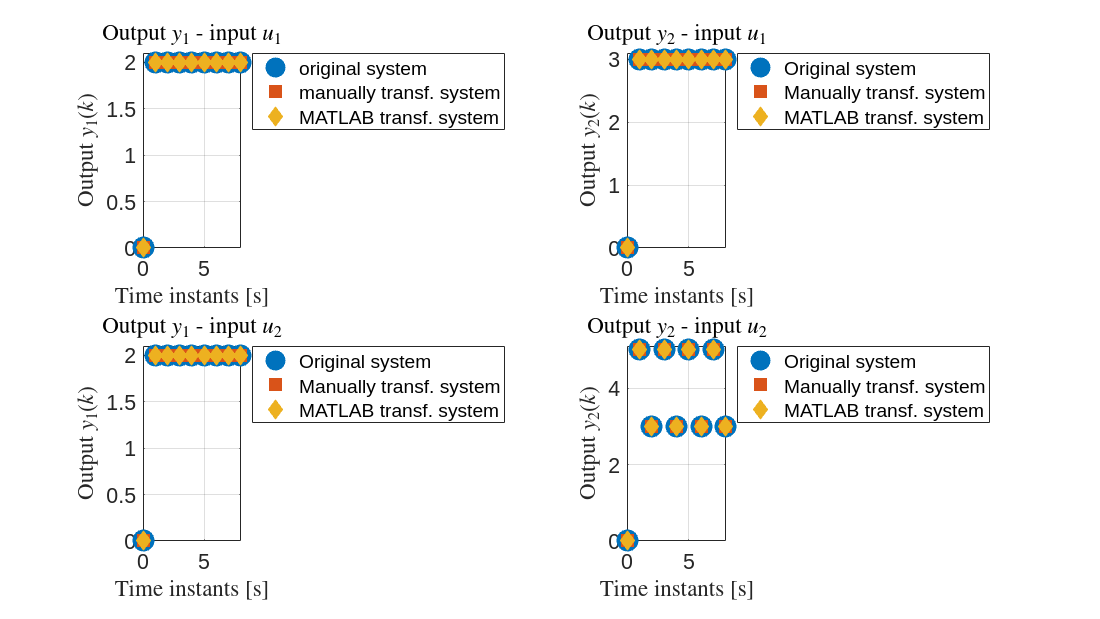

myForcedOutputPlotComparisonMIMO2X2(Y1, Y1hat, Y1ss2, TimeSET)

The **forced output movements** are exaclty the **same**: this is another feature that the state variables transformation preserves.

#### Graphical Comparison of the State  Step Responces

What about the state movement? Is it preserved when we use the state variables transformation?

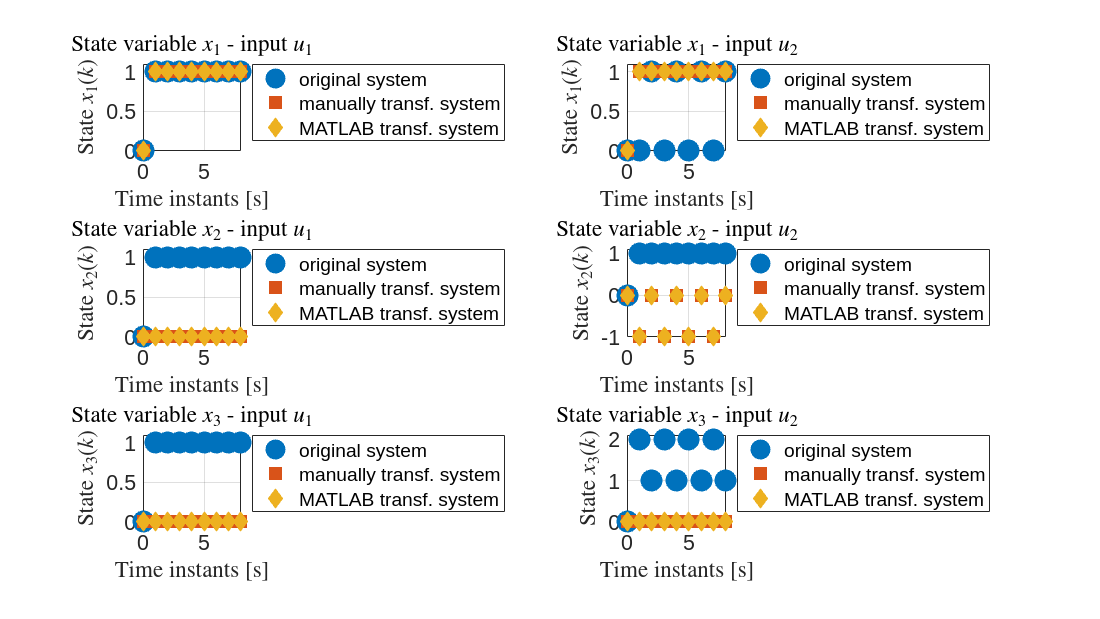

myForcedStatePlotComparisonMIMO2X2(X1, X1hat, X1ss2, TimeSET)

The f**orced state movement** is **not preserved**! The new representation of the system uses state variables that are a linear combination of the original ones. Therefore, it is obvious that the forced state movement may differ in the two representations of the system.

#### Free Output & State Movements

What about free output and state movements?  Does the state variables transformation preserve free movements?

% let's define an initial random state
rng(1);
X0 = randn(3,1);
% and then transform it, using the transformation matrix T1 defined above --> hat_x = T1_inv * x
hat_X0 = T1inv * X0;

% finally, evaluate free output and state movements
[Y1free,~,X1free] = initial(sys1,X0, TimeSET);
[hat_Y1free,~,hat_X1free] = initial(hat_sys1,hat_X0, TimeSET);
[ss2_Y1free,~,ss2_X1free] = initial(ss2_sys1,hat_X0, TimeSET);


#### Graphical Comparison of the  Free Output  Responces

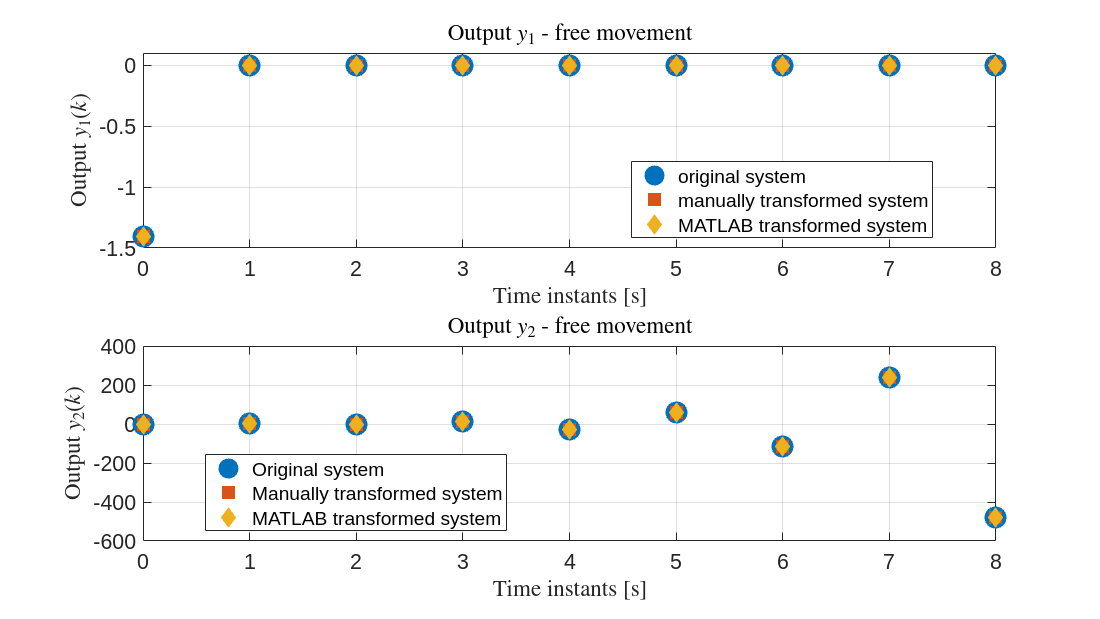

myFreeOutputPlotComparisonMIMO2X2(Y1free, hat_Y1free, ss2_Y1free, TimeSET)

The free** output movements** are exaclty the **same**: this is another feature that the state variables transformation preserves.

#### Graphical Comparison of the  Free State  Responces

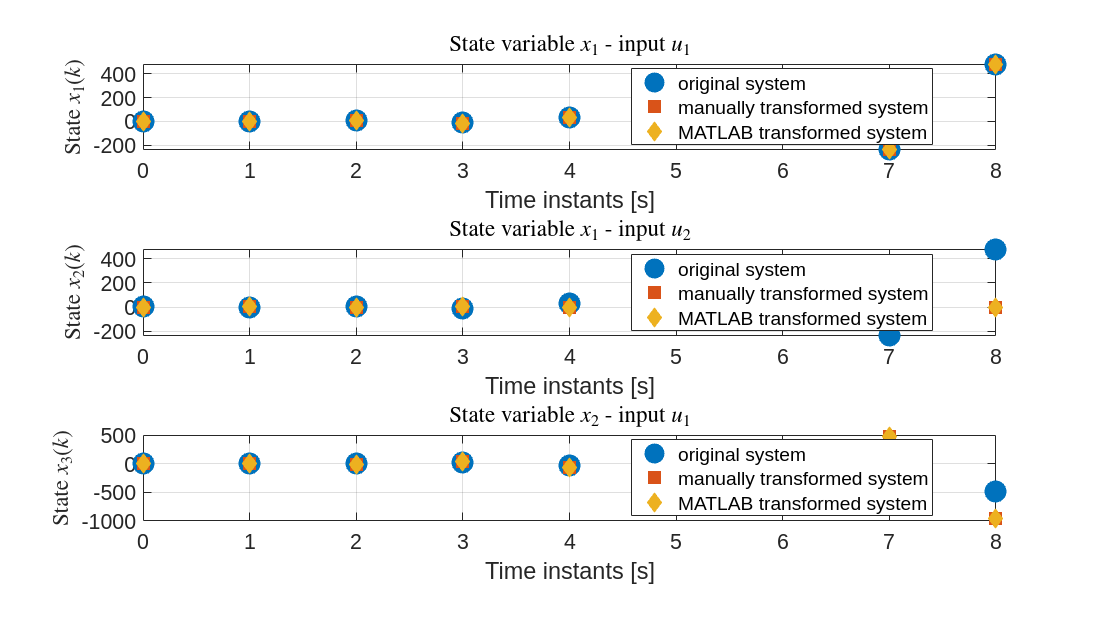

myFreeStatePlotComparisonMIMO2X2(X1free, hat_X1free, ss2_X1free, TimeSET)

The free** state movement** is **not preserved**! The new representation of the system uses state variables that are a linear combination of the original ones. Therefore, it is obvious that the free state movement may differ in the two representations of the system.

## Equivalent State-Space Representations of LTI Systems in MATLAB: a Different Example

Consider now a generic SISO LTI discrete time system


$$\left \{
\begin{array}{l}
x(k+1) = A x(k) + B u(k) \\
y(k) = C x(k) + D u(k)
\end{array}
\right .$$


% a random LTI SISO discrete-time system of Nth order
%
sysOrder = 6; % the state variable vector is a vector of size [sysOrder x 1]

sysD_2 = drss(sysOrder); % <-- the LTI system

X0_D2 = randn(sysOrder,1); % <-- pick a random initial state

Select a generic $$\, T \in {\mathbb R}^{n \times n} \,$ $ non-singular $$n \times n$$ matrix ($$\, {\rm det} (T) \not= 0 \,$$) [where $n$ is the system order] 

T6 = randn(6); % a random matrix as state variables linear transformation
T6inv = inv(T6);

Apply the transformation to the initial state 

T_X0_D2 = T6inv * X0_D2;

and to the system representation

% perform the transformation
T_sysD2 = ss2ss(sysD_2, T6inv);

### Comparing the System Representations: the Eigenvalues

eig(sysD_2.A)

ans =    0.5356 + 0.8066i
   0.5356 - 0.8066i
   0.3846 + 0.0000i
   1.0000 + 0.0000i
   0.7528 + 0.0000i
   0.7892 + 0.0000i


eig(T_sysD2.A)

ans =    0.5356 + 0.8066i
   0.5356 - 0.8066i
   0.3846 + 0.0000i
   1.0000 + 0.0000i
   0.7528 + 0.0000i
   0.7892 + 0.0000i


As expected, the **eigenvalues** are an **invariant feature**.

### Compare Output and State Movements of the System Representations

Let us define a time horizon and a sampling period

Tstop = 100;
Tsampling = 1;

color1 = [0 0.4470 0.7410];
color2 = [0.8500 0.3250 0.0980];

Moreover, let's define an input for the system

SinPeriod = 2.5;
[input_D2, timeSET_D2] = gensig('sine', SinPeriod, Tstop, Tsampling); 
% a sampled sinusoid as input; sampling period Tsampling; period of the
% sinusoidal signal: SinPeriod

Evaluate the system behavior, when starting from the selected initial state, we apply the sinusoidal input. Use both the system representations.

[yD2,~,xD2] = lsim(sysD_2,input_D2,timeSET_D2, X0_D2); % the original representation
[TyD2,~,TxD2] = lsim(T_sysD2,input_D2,timeSET_D2, T_X0_D2); % the new system description

Now we can compare state and output movements, obtained using both the system representations. 

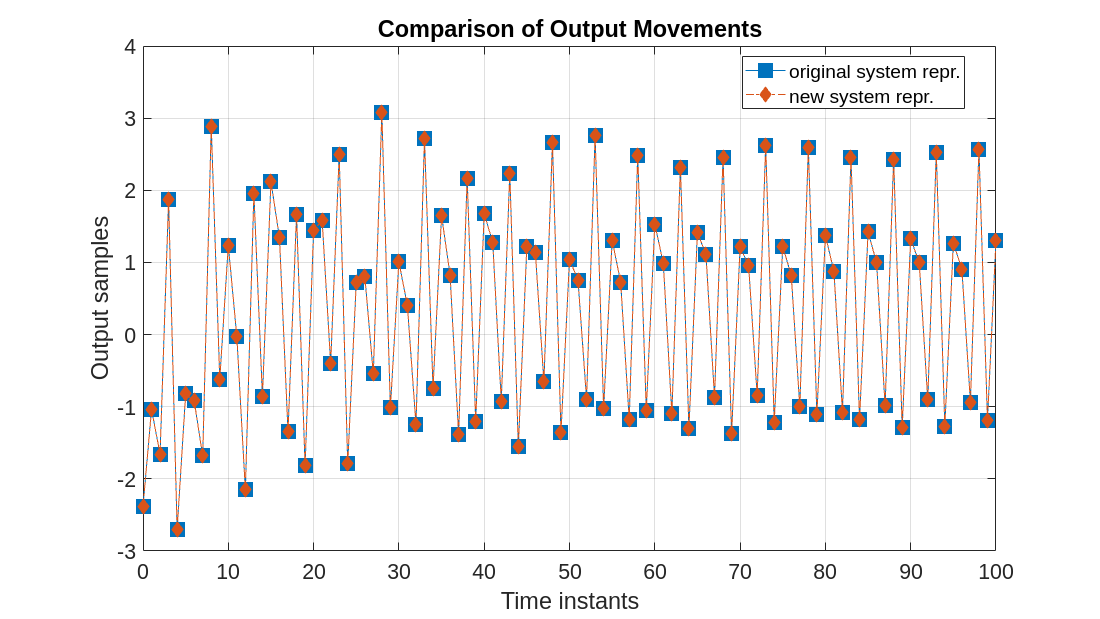

figure('Name','Compare output movements - generic LTI system', ...
       'Units','normalized', 'Position', [0.1, 0.1, 0.8, 0.8]);
plot(timeSET_D2, yD2, 'square-',  "MarkerSize", 14 , "MarkerFaceColor", color1, "MarkerEdgeColor", color1); 
hold on;
plot(timeSET_D2, TyD2, 'diamond-.', "MarkerSize", 8 , "MarkerFaceColor", color2, "MarkerEdgeColor", color2 ); 
grid on; zoom on
xlabel('Time instants'); ylabel('Output samples');
title('Comparison of Output Movements');
legend('original system repr.', 'new system repr.', 'Location','best');
set(gca, 'FontSize', 16);

The output movement has been preserved, when changing the state variables description and the system state-space representation.

The preservation is not true when considering the state movement:

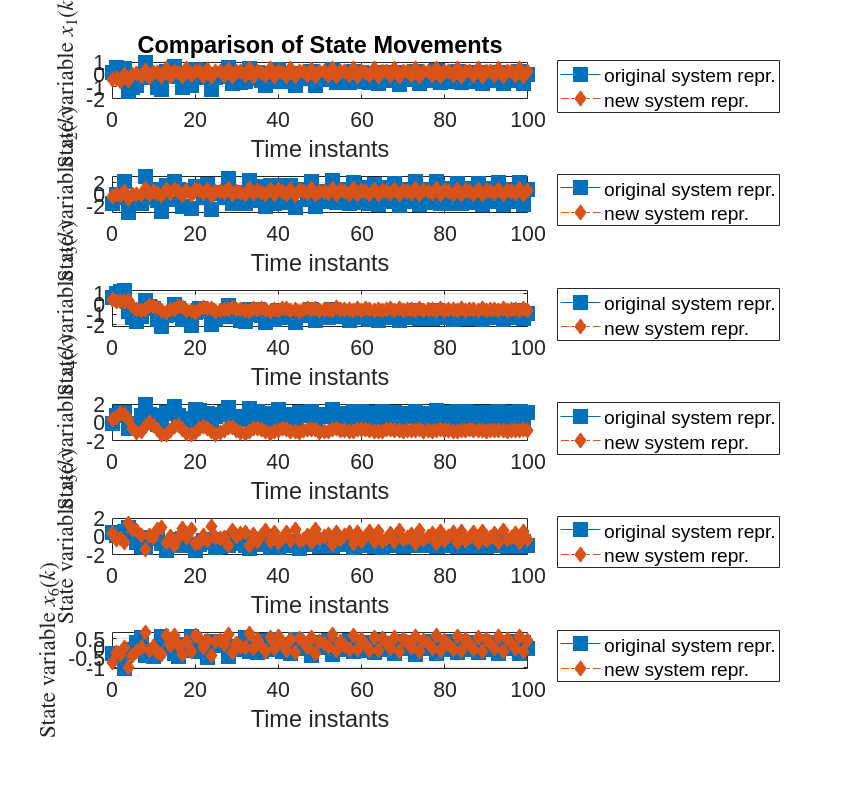

myGenericLTI_StateMovementPlotComparison(xD2, TxD2, timeSET_D2)

## Concluding Remarks

Given the discrete-time LTI dynamic system state-space representation of order $n$:


$$\left \{
\begin{array}{l}
x(k+1) = A x(k) + B u(k) \\
y(k) = C x(k) + D u(k)
\end{array}
\right .$$


and considered the generic non-singular $$n \times n$$ matrix $$\, T \in {\mathbb R}^{n \times n} \,$ $such that


$$\hat x := T^{-1} x $$


then the **equivalent state-space description**: 


$$\left \{
\begin{array}{l}
\hat x(k+1) = T^{-1} x(k+1) = T^{-1} A T \hat x(k) + T^{-1} B u(k) = 
\hat A \hat x(k) + \hat B u(k) \\
y(k) = C T \hat x(k) + D u(k) = \hat C \hat x(k) + D u(k)
\end{array}
\right .$$


**preserves** the **eigenvalues** of the state matrix. Moreover, the transformation preserves also the **output movement. **

Given a generic admissible input sequence $u(k) \; ( k=0,\;1,\;\ldots )$ and for each possible initial state $x(0)$,  any equivalent state-space representation of the given LTI system allows one to determine the same output movement. This property may be proved by using the theoretical expression of the state and output movements and applying the state-space transformation to it.

 ,  